Calculates the normalized force in tendon for Thelen2003 muscle model.

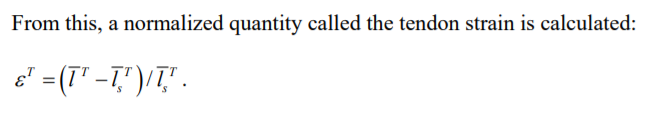

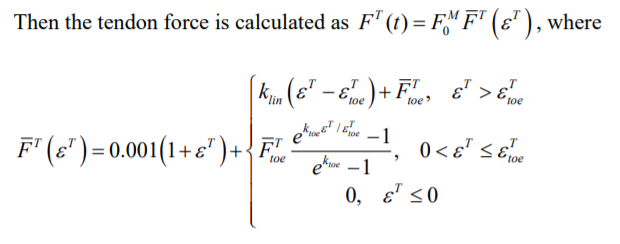

function FT = Thelen2003_Tendon_Force(norm_ten_len, norm_ten_slack_len)
    % define constants for tendon force calculation
    eT_0 = 0.033; % tendon strain due to maximum isometric force
    eT_toe = 0.609*eT_0; % tendon strain above which tendon force is linear with respect to tendon strain
    FT_toe = 0.333333; % normalized tendon force above which tendon force is linear with respect to tendon strain
    k_lin = 1.712/eT_0; % a linear shape factor
    k_toe = 3; % an exponential shape factor
    
    FT = zeros(size(norm_ten_len));
    for i = 1:length(norm_ten_len)
        eT = (norm_ten_len(i) - norm_ten_slack_len)/norm_ten_slack_len;
        
        FT_1 = 0.001 * (1 + eT);
        if eT > eT_toe
            FT(i) = FT_1 + k_lin * (eT - eT_toe) + FT_toe;
        elseif 0 <= eT && eT <= eT_toe
            FT(i) = FT_1 + FT_toe * (exp(k_toe*eT/eT_toe) - 1) / (exp(k_toe) - 1);
        elseif eT <= 0
            FT(i) = FT_1;
        end
    end

end